Parameters

M=1.47*1e4;     % In Oe
Y=1.76e7;     % Gyromagnetic Ratio
H_y0=50;  % Transverse AC field amplitude
a=0.1;     % Damping parameter
w=9e9;     % Transverse AC field frequency
Hz=-1000:1:1000;
w_0=abs(Y)*sqrt(Hz.*(Hz+M));
%w_0=6e9:10000:11e9;

Lorentzian

fmr= (1*power(abs(Y),2)*M*H_y0*a*abs(Y)*M*w)./( power(w_0.^2-w^2,2) + power(a*abs(Y)*M*w,2));

Plot

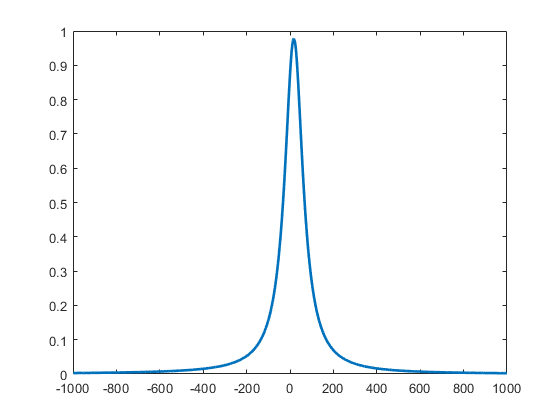

plot(Hz,fmr,'LineWidth',2)

% s=-1*power(abs(Y),2)*M*H_y0*a*abs(Y)*M*w;
% t=power(a*abs(Y)*M*w,2);
% fmr2=s./( power(Y^2.*Hz.^2 + Y^2.*M.*Hz - w^2,2)+t );
% plot(Hz,fmr2)
% plot(w_0,fmr);hold on;
% w_0=11e9:10000:13e9;
% fmr= (-1*power(abs(Y),2)*M*H_y0*a*abs(Y)*M*w)./( power(w_0.^2-w^2,2) + power(a*abs(Y)*M*w,2));
% plot(w_0,fmr);hold off;

Derivative FMR

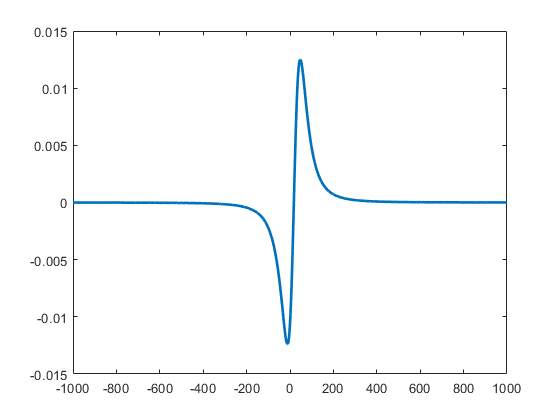

% s=-1*power(abs(Y),2)*M*H_y0*a*abs(Y)*M*w;
% t=power(a*abs(Y)*M*w,2);
% dfmr=(-2*s*(2*Y^4.*Hz.^3 + 3*Y^4*M.*Hz.^2 + (Y^2*M^2 - 2*w^2*Y^2).*Hz - w^2*Y^2*M))./( ((Y^2.*Hz.^2 + Y^2*M.*Hz -w^2).^2+ t).^2 );
% plot(Hz,dfmr)
s=-1*power(abs(Y),2)*M*H_y0*a*abs(Y)*M*w;
t=power(a*abs(Y)*M*w,2);
syms x;
f=s./( power(Y^2*x^2 + Y^2*M*x - w^2,2)+t );
dfmr=subs(diff(f,x),x,Hz);
plot(Hz,dfmr,'LineWidth',2)